# Object Detection with Machine Learning

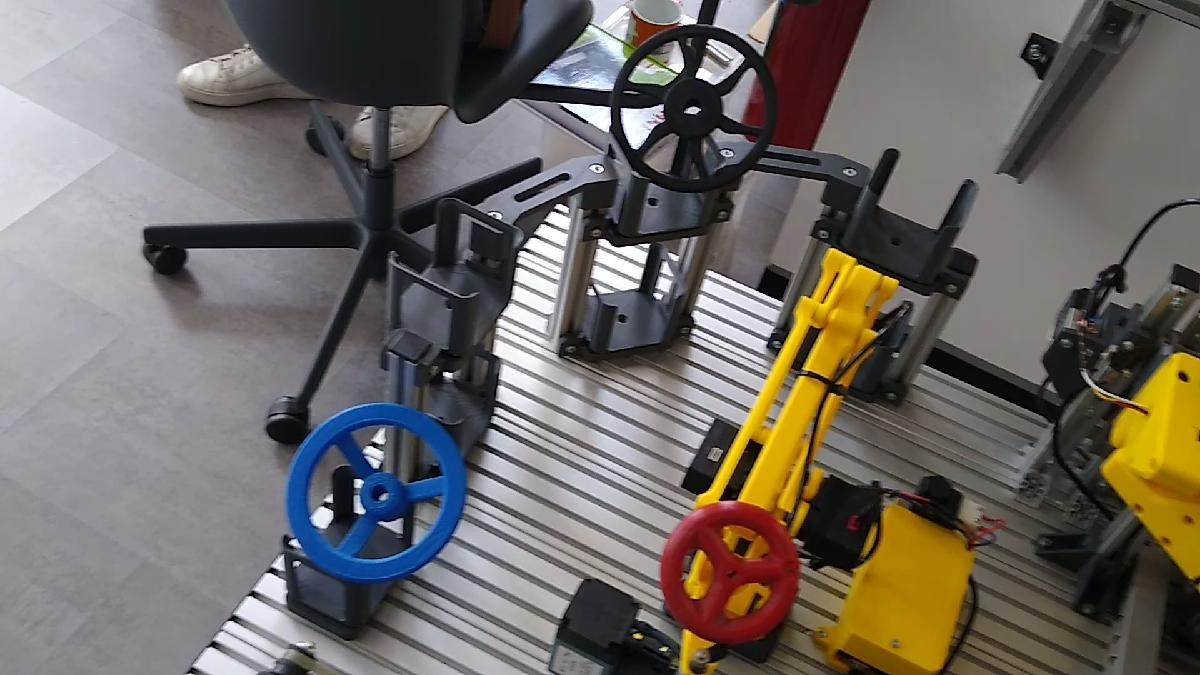

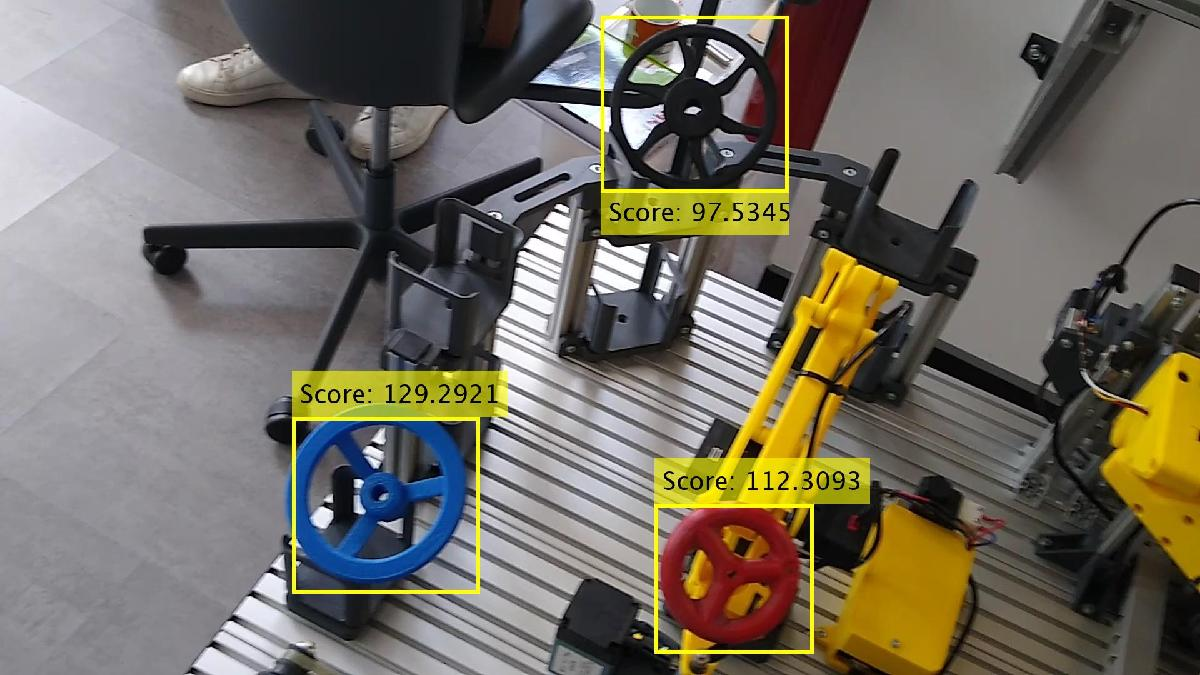

Our project leverages MATLAB's machine learning (ML) capabilities to automate valve detection in images. Valves play a crucial role in industries like manufacturing and utilities. Automating their detection enhances efficiency and accuracy.

Key Steps:

- Data Acquisition: We collect a dataset of valve images, each annotated with bounding boxes indicating valve locations.

- Data Preprocessing: Using MATLAB's Image Processing Toolbox, we resize, normalize, and augment the dataset for optimal training.

- Model Training: Employing MATLAB's ML and Computer Vision Toolboxes, we train a model using  traditional classifiers.

Outcomes:

- Accurate valve detection across diverse industrial environments.

- Increased productivity and reliability through automation.

- Reduced manual inspection efforts and associated errors, leading to cost savings and improved safety.

Future Scope:

- Fine-tuning the model for specific valve types and environments.

- Extending the system to detect other industrial components or anomalies.

- Integration with MATLAB's IoT functionalities for real-time monitoring and control.

Our project highlights the synergy between advanced ML techniques and MATLAB's toolset, driving transformative advancements in industrial automation.

### Loading the Ground Truth Data and Training the ACF Object Detector

Before detecting objects with the ACF Object Detector, we need to load the ground truth data for the valves dataset. This data is stored in a ".mat" file. First, we'll load the dataset, and then update the image file locations to match our system. To accomplish this, execute the following code section. Afterward, we'll proceed with object detection using the ACF Object Detector.

### Training the ACF Object Detector

Once the ground truth data is loaded and preprocessed, the ACF Object Detector is trained. This involves using the ground truth data to train the detector to recognize valves in images. After training, the detector will be capable of identifying valves in new, unseen images.

The function `loadAndDetectBoxes()` encapsulates these tasks and returns three important variables: `imdsTest`, `gTruthTest`, and `bboxes`. These variables contain the necessary data and information for further analysis and evaluation of the ACF Object Detector's performance.

load 'acfDetector.mat';
videoFile='valves.mp4';
bboxes = detectValvesInVideo(videoFile, acfDetector)

### display some image from test data 

outputVideoFile='detectingObject'

outputVideoFile = 'detectingObject'

writeDetectedBoxesToVideo(videoFile, outputVideoFile, bboxes)

Dot indexing is not supported for variables of this type.

Error in writeDetectedBoxesToVideo (line 16)
        detectedBoxes = bboxes.Boxes{idx};

### Detect Using the Trained Detector

In this  phase, we embark on the pivotal task of object detection within our testing dataset. This undertaking follows an extensive period of training our ACF (Aggregate Channel Features) model, which has been meticulously tailored to recognize specific objects of interest.

### omprove result Results

Intersection over Union

A standard method for quantifying the accuracy of a single bounding box is to calculate its overlap ratio with the ground truth, also known as the Intersection over Union (IoU).

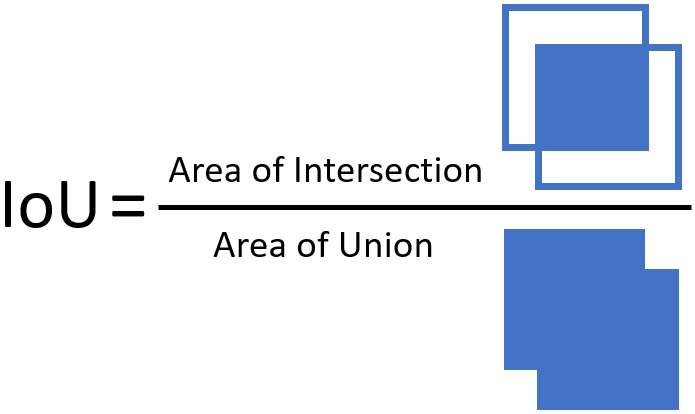

Detect only boxes with higher score values

In our previous model analysis, we observed an abundance of bounding boxes in certain images, a scenario we aim to address in our current iteration. To mitigate this, we've adopted two strategic approaches. First, we employ the Intersection over Union method, enhancing the precision of our object detection. Secondly, we selectively filter out boxes with higher score values, ensuring the prioritization of more accurate detections.

save Result in Pdf File .

%matlab.internal.liveeditor.openAndConvert('ObjectDetectionWithML.mlx', 'ValveDetection.pdf', 'HideCode',false);

### Summary and Next Steps

Summary: Despite our efforts to enhance the model, we faced inconsistencies in valve detection. Exploring a deep learning approach, especially with the YOLO algorithm, might offer better outcomes. However, deep learning training requires significant time and resources. Traditional methods, though satisfactory, may occasionally miss detections. Yet, the potential of deep learning in such projects remains promising.

Next Steps: To address these challenges, we plan to refine the model further by optimizing training data and parameters. Additionally, we aim to explore the integration of deep learning techniques, such as YOLO, to potentially enhance detection accuracy and robustness in valve detection tasks.